## Simulación de Ruido Blanco

Podemos simular ruido blanco de dos maneras. La primera es mediante una distribución normal, obteniendo así una distribución de probabilidad gaussiana; la segunda, mediante una distribución uniforme (valores equiprobables). Cabe señalar que las distribuciones, por sí mismas, no constituyen el ruido, sino que representan las probabilidades de generar los valores en la muestra de dicho ruido. 

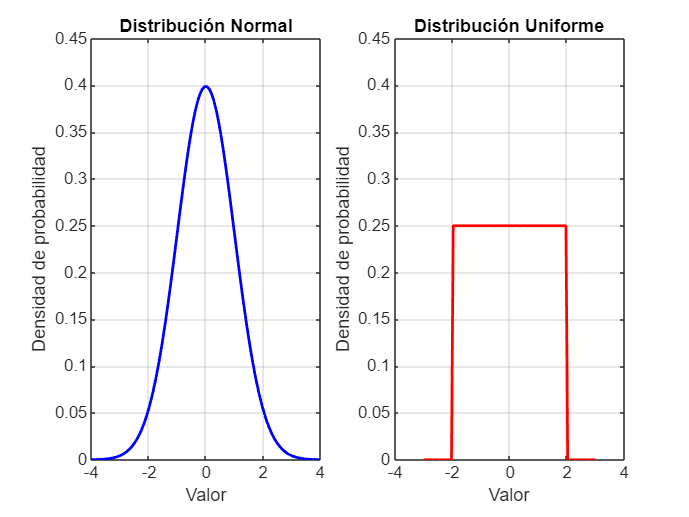

mu = 0;      
sigma = 1;    
a = -2;       
b = 2;        

x_normal = linspace(mu - 4 * sigma, mu + 4 * sigma, 100); 
x_uniform = linspace(a - 1, b + 1, 100); 

pdf_normal = normpdf(x_normal, mu, sigma); 
pdf_uniform = unifpdf(x_uniform, a, b);    

figure;

% Distribución normal
subplot(1, 2, 1);
plot(x_normal, pdf_normal, "b", "LineWidth", 1.5);
title("Distribución Normal");
xlabel("Valor");
ylabel("Densidad de probabilidad");
ylim([0, 0.45])
grid on;

% Distribución uniforme
subplot(1, 2, 2);
plot(x_uniform, pdf_uniform, "r", "LineWidth", 1.5);
title("Distribución Uniforme");
xlabel("Valor");
ylabel("Densidad de probabilidad");
ylim([0, 0.45])
grid on;

Podemos modificar/modular las distribuciones usando los siguientes parámetros: 

- de desplazamiento (desplazarlo en el eje X)

- de extensión (modula la anchura de la distribución)

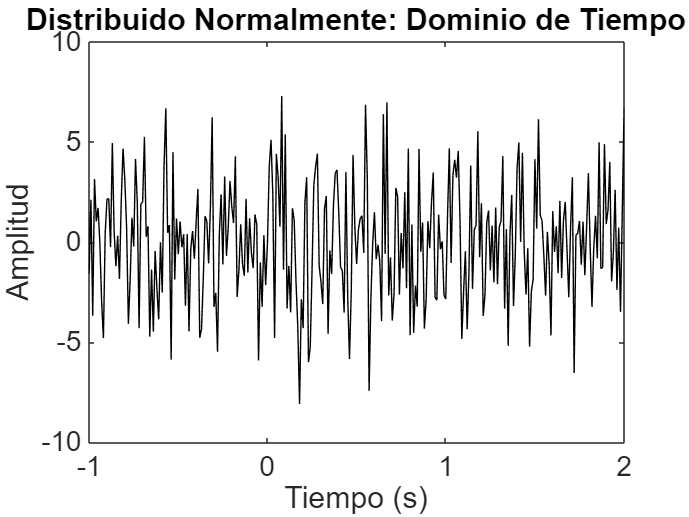

srate  = 100; % sampling rate in Hz
time   = -1:1/srate:2;
pnts   = length(time);

% Frecuencias para el espectro de potencia
hz = linspace(0,srate/2,floor(length(time)/2)+1);


% Parametros de ruido
stretch = 3;
shift   = 0;

% Generación de datos aleatorios
noise = stretch*randn(size(time)) + shift;

figure
plot(time,noise,"k")
set(gca,"fontsize",15)
title("Distribuido Normalmente: Dominio de Tiempo")
xlabel("Tiempo (s)"), ylabel("Amplitud")

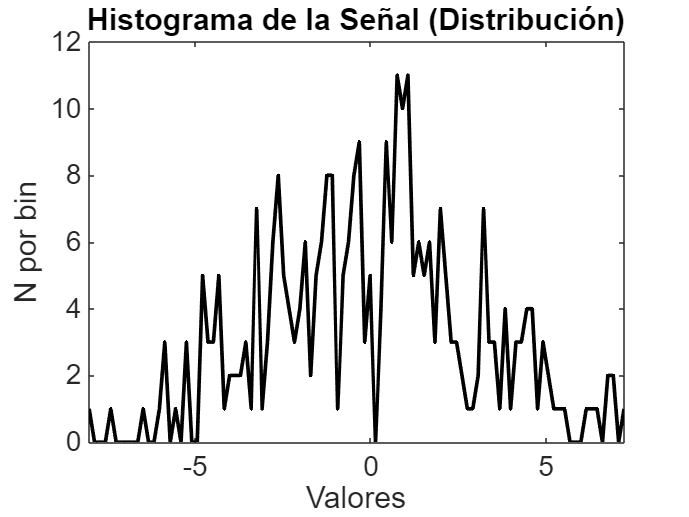


figure
[y,x] = hist(noise,100);
plot(x,y,"k","linew",2)
xlabel("Valores"), ylabel("N por bin")
title("Histograma de la Señal (Distribución)")
set(gca,"fontsize",15,"xlim",[min(x) max(x)])

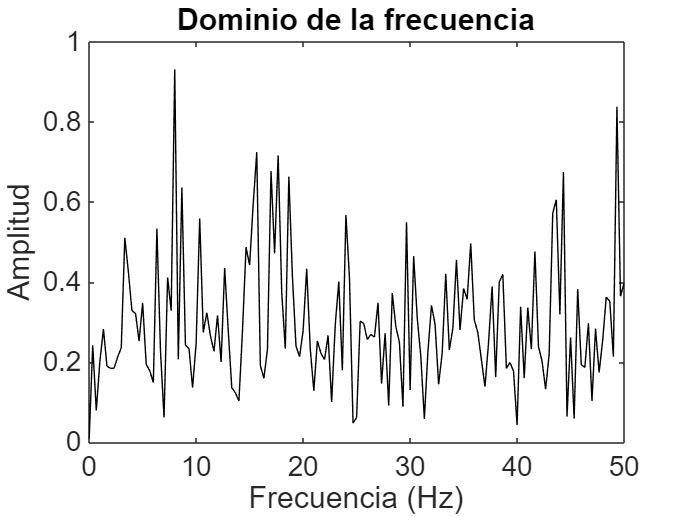


figure
amp = abs(fft(noise)/pnts);
amp(2:end) = 2*amp(2:end);
plot(hz,amp(1:length(hz)),"k")
title("Dominio de la frecuencia")
set(gca,"fontsize",15)
xlabel("Frecuencia (Hz)"), ylabel("Amplitud")

## Simulación de Ruido Rosa

Tiene un espectro de potencia que disminuye a media que se aumenta la frecuencia


$$\frac{1}{f^c }$$


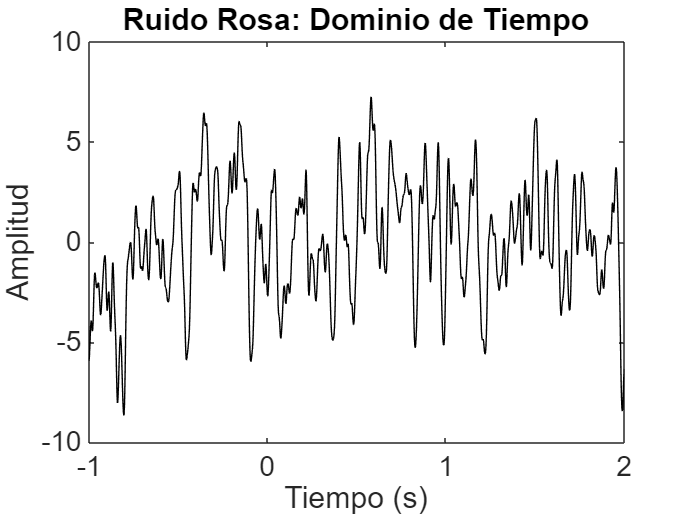

srate = 500;
time  = -1:1/srate:2;
pnts  = length(time);
hz    = linspace(0,srate/2,floor(length(time)/2)+1);

% Espectro de Amplitud 1/f
ed = 50; % Parámetro de decaimiento exponencial 
as = rand(1,floor(pnts/2)-1) .* exp(-(1:floor(pnts/2)-1)/ed);
as = [as(1) as 0 0 as(:,end:-1:1)];

% Coeficientes de Fourier
fc = as .* exp(1i*2*pi*rand(size(as)));

% Transformada inversa de Fourier para generar el ruido
noise = real(ifft(fc)) * pnts;


figure
plot(time,noise,"k")
set(gca,"fontsize",15)
title("Ruido Rosa: Dominio de Tiempo")
xlabel("Tiempo (s)"), ylabel("Amplitud")

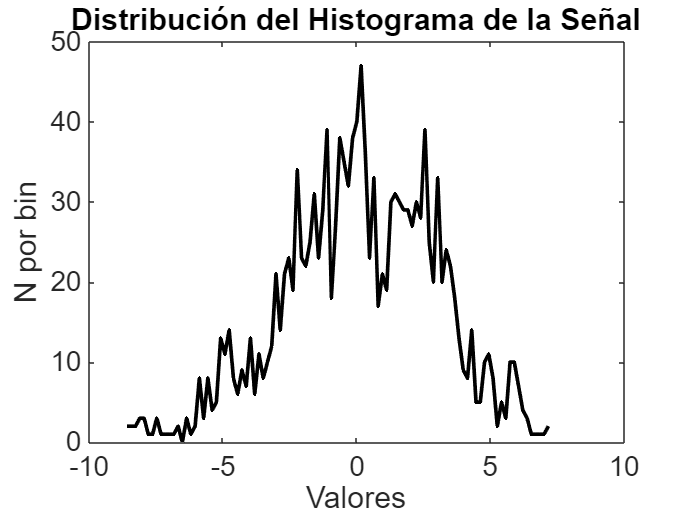


figure
[y,x] = hist(noise,100);
plot(x,y,"k","linew",2)
xlabel("Valores"), ylabel("N por bin")
title("Distribución del Histograma de la Señal")
set(gca,"fontsize",15)

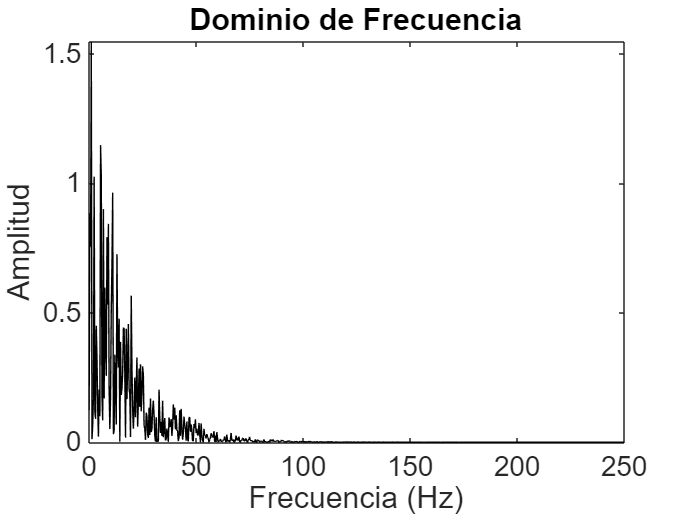


figure
amp = abs(fft(noise)/pnts);
amp(2:end) = 2*amp(2:end);
plot(hz,amp(1:length(hz)),"k")
title("Dominio de Frecuencia")
set(gca,"fontsize",15)
xlabel("Frecuencia (Hz)"), ylabel("Amplitud")